# Design a Path Follower with a DJI®  N3 Autopilot and NVIDIA® Jetson Nano using DJI Onboard ROS SDK

This example shows how to use UAV Toolbox and ROS Toolbox to design a waypoint follower for a quadcopter that uses [DJI N3 Autopilot](https://www.dji.com/n3).

This example uses [DJI Onboard SDK](https://developer.dji.com/onboard-sdk/documentation/introduction/homepage.html) which provides a [ROS wrapper](https://github.com/dji-sdk/Onboard-SDK-ROS) that is used to interface with the ROS Toolbox.

In this example, you will learn how to:

- Configure a Simulink model which defines a quadcopter mission of a DJI N3 Flight Controller by using a set of waypoints, by using UAV Toolbox and ROS Toolbox

- Start DJI Onboard ROS SDK on a Compute board

- Set up the required custom messages using ROS Toolbox on the host computer

- Simulate and deploy the Simulink model on the Compute board

This example uses the UAV Waypoint Follower block from the UAV Toolbox and [ROS Publish](https://www.mathworks.com/help/ros/ref/publish.html)/[ROS Subscribe](https://www.mathworks.com/help/ros/ref/subscribe.html) blocks from the ROS Toolbox.

## Prerequisites

- If you are new to Simulink, watch the [Simulink Quick Start](https://www.mathworks.com/videos/simulink-quick-start-78774.html) video.

- Refer [Getting started with ROS in Simulink](https://www.mathworks.com/help/ros/ug/get-started-with-ros-in-simulink.html) that shows how to use Simulink blocks for ROS

## Required Products

The following products are required for this example:

- Simulink Coder

- ROS Toolbox

- UAV Toolbox

### **Required Hardware**

To run this example, you will need the following hardware:

- Any DJI Onboard SDK supported hardware. You can find the list in this [link](https://developer.dji.com/products/#!/onboard). In this example we have used [DJI N3 Autopilot](https://www.dji.com/n3).

- Compute board with an available TTL UART port. In this example, we use NVIDIA® Jetson Nano.

- Serial-to-USB FTDI converter

- DJI® Lightbridge or SBUS based Remote Controller

- Battery to power the DJI N3 Autopilot

### **Setup**

 Follow the instructions mentioned in the 'Setting Up DJI Autopilot and Onboard SDK' document to setup the Autopilot and Compute board. 

## Waypoint Follower Configuration

The *ROS_DJI_waypoint_follower *model is configured for a quadcopter mission consisting of take-off, waypoint follower and land. This model shows how to receive waypoints from an external ‘Path Planner’ and follow it.

Copy the files into a separate working directory and makes that as the current working directory.

open_system('ROS_DJI_waypoint_follower');

The* ROS_DJI_waypoint_follower* model contains five subsystems, namely TakeOff Service, Verify Successful TakeOff, Waypoint Guidance, Land Service and Plotting. The ‘Flight Stage Controller’ controls the execution of the five subsystems. 

The inputs u1,u2,u3 and u4 are zero at the beginning. This ensures that the TakeOff Service subsystem is executed first. The plotting subsystem can be enabled/disabled using the Slider Switch.

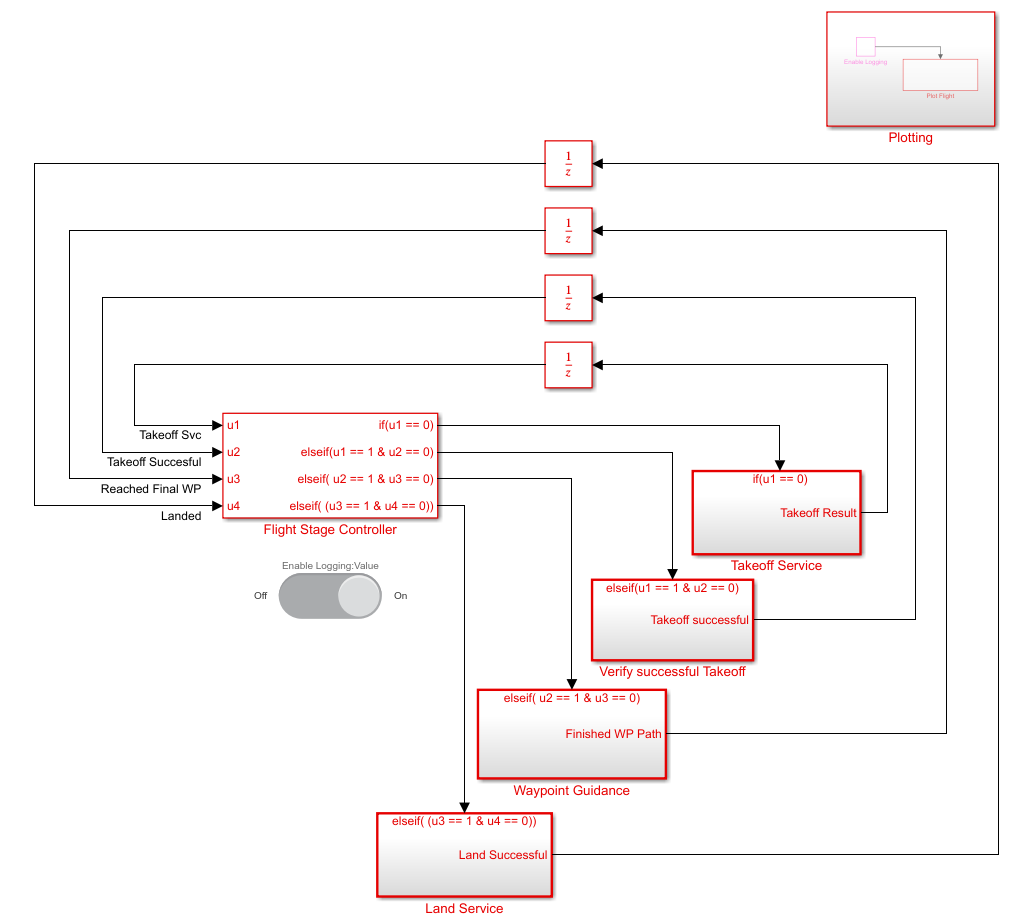

### **TakeOff Service / Land Service**

            The TakeOff Service and the Land service subsystems call the ‘dji_sdk/drone_task_control’ service with the TakeOff command and Land command respectively.

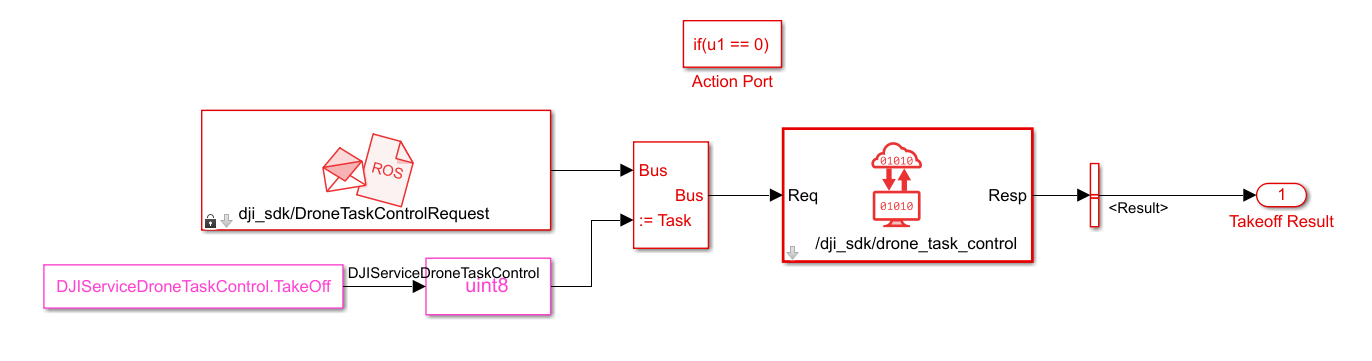

### **Verify Successful Takeoff**

            The Verify Successful Takeoff subsystem verifies if the takeoff is successful by subscribing to the ‘dji_sdk/flight_status’ and ‘dji_sdk/display_mode’ topics. Once the takeOff is successful, the subsystem outputs a positive Boolean value (Takeoff successful signal). When the Flight Stage Controller receives this signal, it activates the Waypoint Guidance subsystem.

### **Waypoint Guidance**

            The Waypoint Guidance subsystem is designed such that it receives the waypoints from an external ‘Path Planner’. The ‘Receive Waypoints from External Path Planner’ subsystem has a ROS subscribe block, which reads the ‘/waypoints’ topic, to which the Waypoints are published.

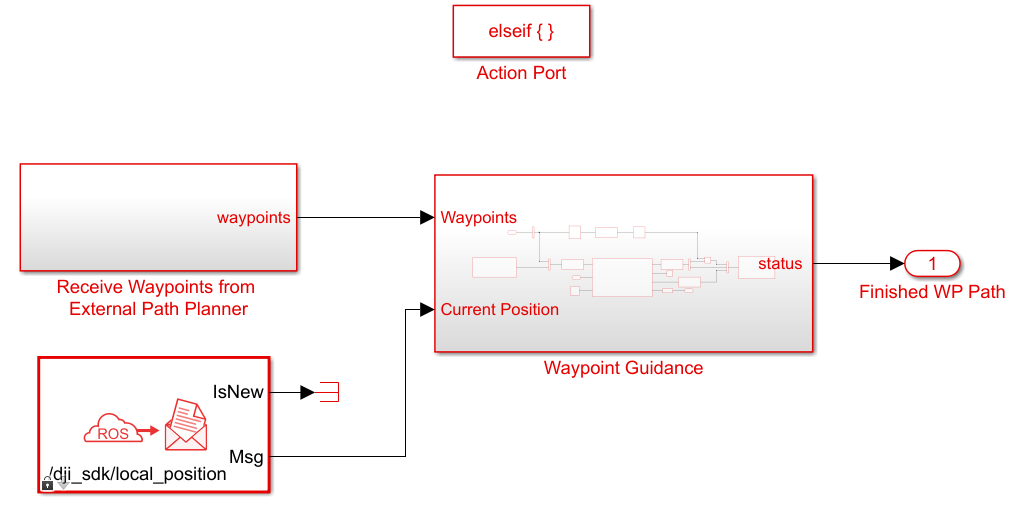

The Waypoint Guidance/Waypoint Guidance subsystem uses the UAV Waypoint Follower block. The UAV Waypoint Follower block computes a desired heading for the UAV based on the current pose, lookahead distance, and a given set of waypoints. The Current Pose is obtained by subscribing to the ‘dji_sdk/local_position’ topic and the Heading is calculated using the ‘dji_sdk/velocity’ topic. The Waypoint Publish subsystem publishes the X,Y,Z and Yaw to the ‘dji_sdk/flight_control_setpoint_ENUposition_yaw’ topic. 

**NOTE**: The ‘dji_sdk/flight_control_setpoint_ENUposition_yaw’ topic expects the X,Y **position offset **and Z, yaw as absolute values. Refer to the [dji_sdk wiki](http://wiki.ros.org/dji_sdk) for more information.

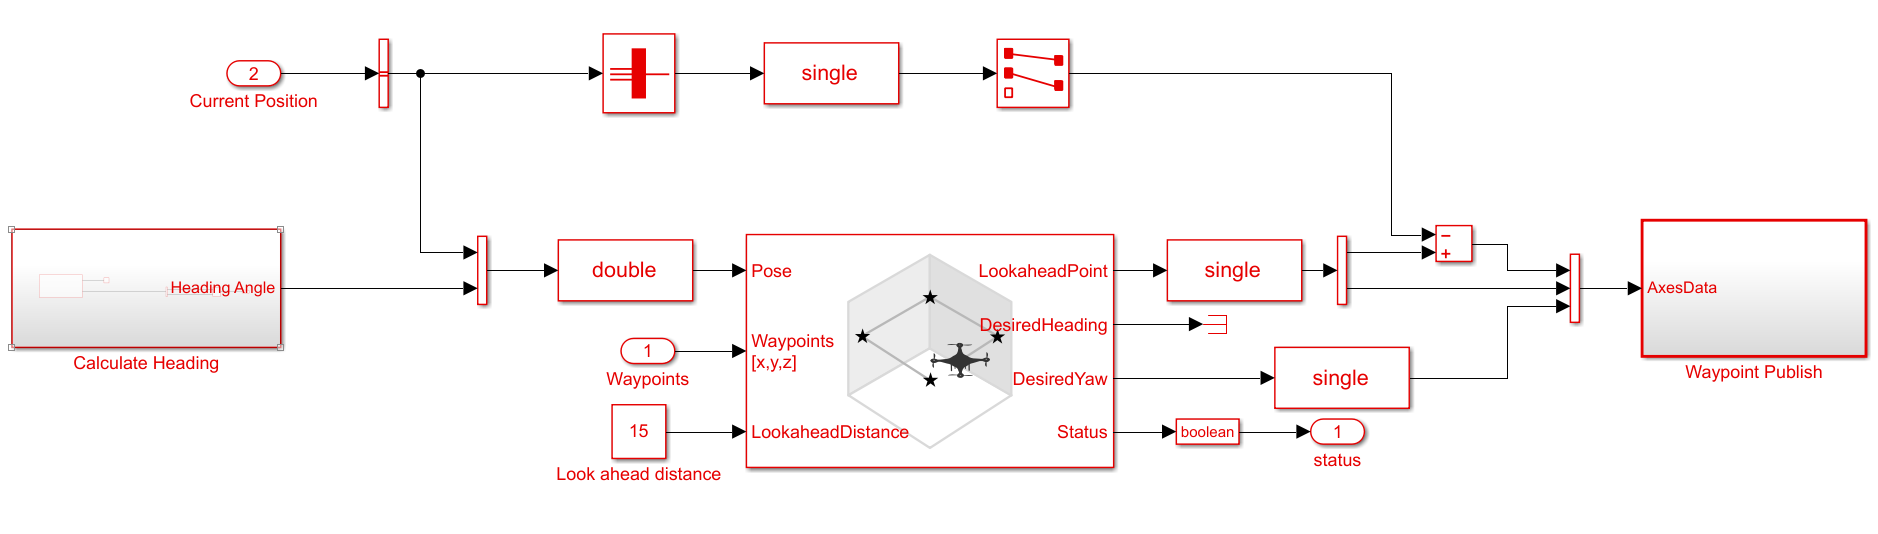

### **Plotting**

            The Plotting subsystem is enabled using the slider switch in the model at the root level. The [UAV Animation](https://www.mathworks.com/help/robotics/ref/uavanimation.html) block, used in this subsystem, visualizes the UAV flight path and attitude. The quadcopter position and attitude are subscribed using the ‘dji_sdk/local_position’ and ‘dji_sdk/attitude’ topics respectively. Enable this subsystem during Simulation only, as there is no effect during deployment.

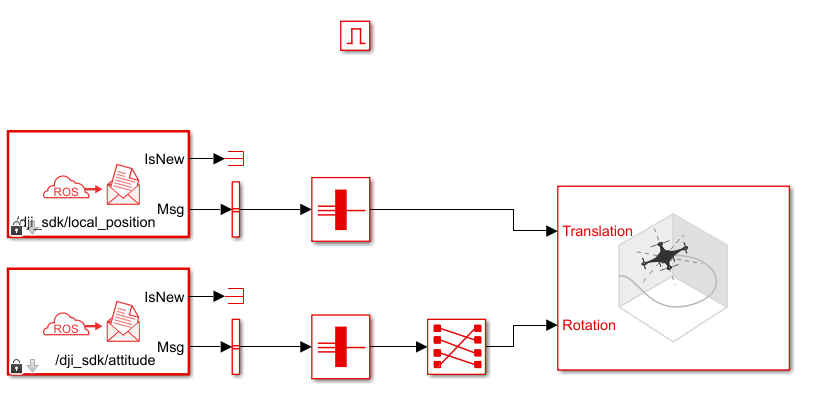

## Task 1 - Start DJI SDK on Compute board

To start DJI SDK on the Compute board:

- Follow the instructions mentioned under the topic 'Setting Up DJI Autopilot and Onboard SDK' to setup the Autopilot and Compute board.

- After making the connections as mentioned, open the DJI Assistant 2 for Autpoilot on Host development computer.

- Ensure the SDK->Enable Api is checked and then click on Start Simulating.

- On your compute board, launch the dji_sdk by following the below steps:

- CD to your catkin workspace where ROS DJI_SDK is built. Remember this path as it will be used in configuration settings of the Simulink model.

- Execute the below command in terminal:

*>>roslaunch dji_sdk sdk.launch*

On another terminal, start the demo flight control sample code provided by DJI SDK by following the steps mentioned [here](http://wiki.ros.org/dji_sdk/Tutorials/Running%20the%20flight%20control%20sample%20code). This step ensures that the setup is ready without MATLAB/Simulink. Stop the demo example.

## Task 2 - **Start ROS Node on MATLAB and Set Up Custom Messages**

Perform the following steps in MATLAB on the host computer to start the ROS node:

- Start the ROS node and connect to the ROS Master running on the Compute board. In this case, the IP address of the NVIDIA® Jetson that we have connected is ‘172.18.188.129’. (Check the IP address of your compute board and use it in the below command)

rosinit('172.18.188.129')

- Verify that the dji_sdk ros node is detected, by executing the below command:

rosnode list

Perform the following steps in MATLAB on the host computer to set up custom messages:

- The DJI ROS SDK has some services, which are of custom message type, and are not shipped by default by the ROS toolbox. Refer [ROS Custom Message Support](https://www.mathworks.com/help/ros/ug/ros-custom-message-support.html), [Create Custom Messages from ROS Package](https://www.mathworks.com/help/ros/ug/create-custom-messages-from-ros-package.html) and [rosgenmsg](https://www.mathworks.com/help/ros/ref/rosgenmsg.html) for more information on how to use it in MATLAB. Note that you may have to install Python, CMAKE and C++ compiler for this. Refer [ROS System Requirements](https://www.mathworks.com/help/ros/gs/ros-system-requirements.html) for the versions corresponding to your platform as mentioned in the setup document. The .SRV and package.xml for this example are part of this submission. Use the following commands to find the location of the example DJI Service package. Ensure that the directory *dji_task_control_package* exists in your MATLAB current working directory before running this code. 

exampleDJIPackages = fullfile(pwd,'dji_task_control_package');

- Execute the following command and follow the instructions on your MATLAB Command Prompt.

rosgenmsg(exampleDJIPackages);

- If javaclasspath.txt is not present, you may be prompted to create it. Click Yes and copy paste the different .jar files locations in this file. 

## TASK 3 - Perform Simulation

The following figure shows the ROS Node block diagram during simulation. The ‘Path Planner’ node is not shown below because it could be on any device.

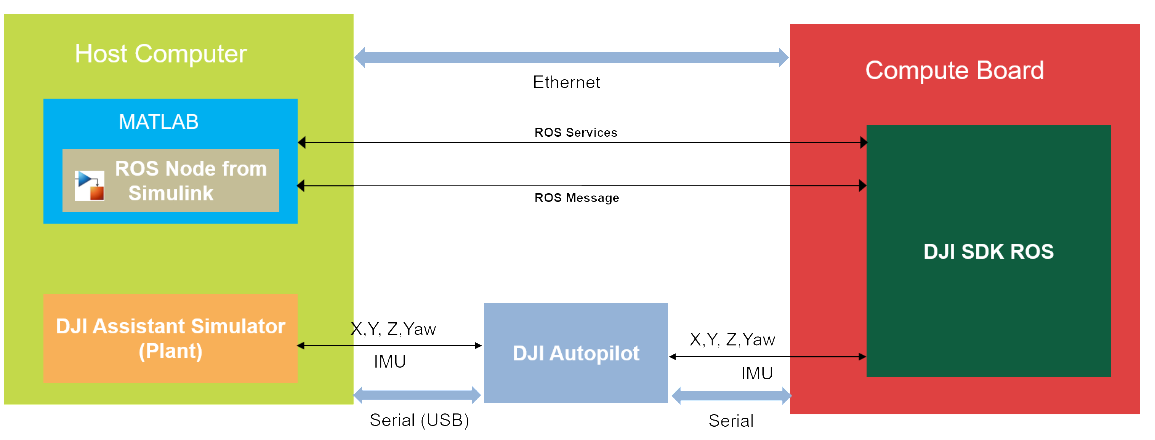

Perform the following steps to simulate the model and visualize the simulation:

- Ensure you have executed the 'demo_flight_control' example shipped by the DJI Onboard ROS SDK by executing '*rosrun dji_sdk_demo demo_flight_control*' command in a terminal on the Compute board (you can refer to this [link](http://wiki.ros.org/dji_sdk/Tutorials/Running%20the%20flight%20control%20sample%20code) for details). This is required because the topic 'dji_sdk/local_position' sometimes does not returning the correct values when Simulating from MATLAB. 

- Open the *ROS_DJI_waypoint_follower* model. This model is configured to use ROS as the Hardware board.

open_system('ROS_DJI_waypoint_follower');

- Configure the device parameters in Configuration parameters -> Hardware Implementation -> Target hardware resources, by providing the device IP address (which you used above to initialize ROS Node), username and password.

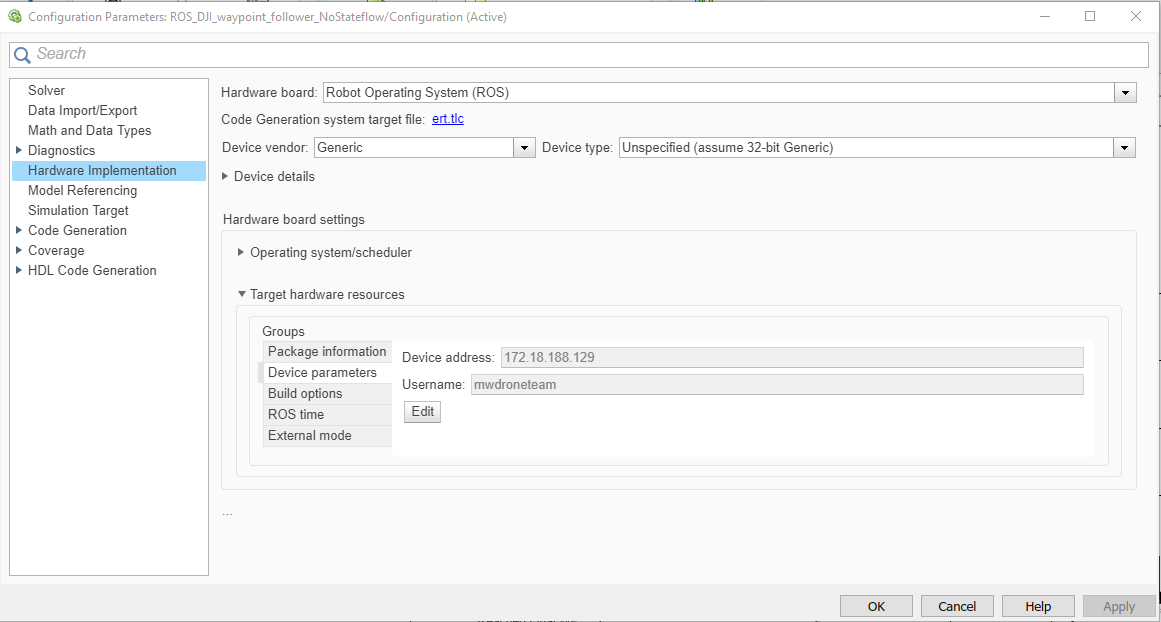

- Mention the ROS folder on compute board and catkin workspace in which the DJI ROS SDK has been built at Configuration parameters -> Hardware Implementation -> Target hardware resources -> Build Options

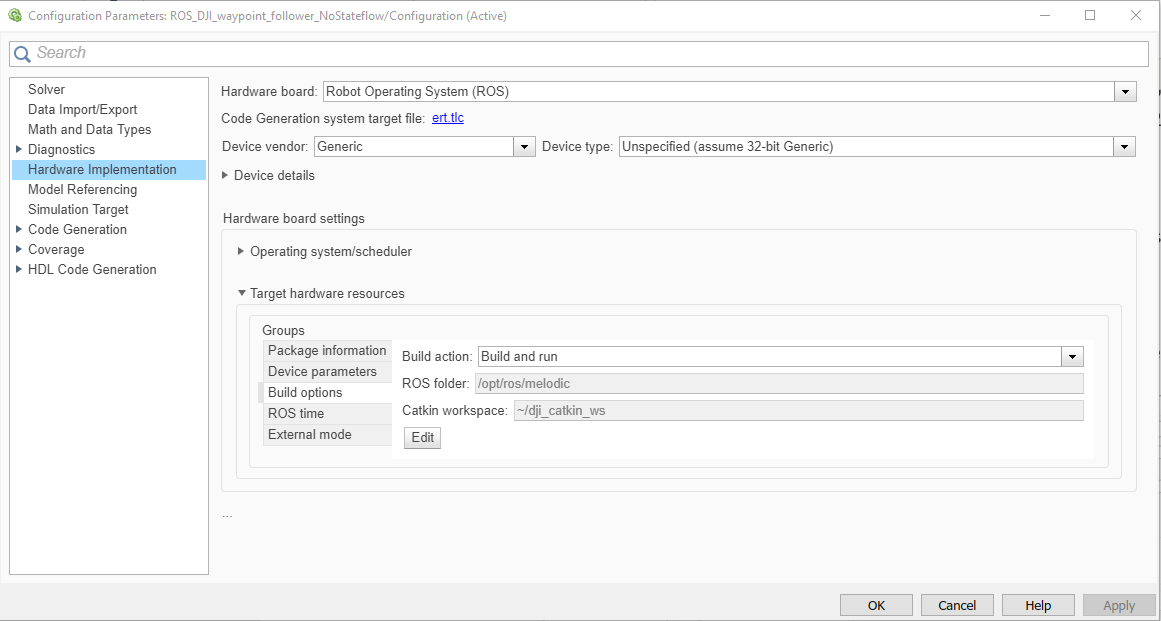

- Click Apply and then OK after making the above changes in the Configuration parameters. For more information on configuring a model for ROS, refer to this [link](https://www.mathworks.com/help/ros/ug/generate-a-standalone-ros-node-from-simulink.html).

- Ensure that the ROS Message type in ROS Blank Message block inside Takeoff Service subsystem and Land Service subsystem is set to *dji_sdk/DroneTaskControl*. You can execute the below commands for the same.

blank_message_takeOff = 'ROS_DJI_waypoint_follower/Takeoff Service/Blank Message';
blank_message_land = 'ROS_DJI_waypoint_follower/Land Service/Blank Message';
set_param(blank_message_takeOff,'messageType','dji_sdk/DroneTaskControlRequest');
set_param(blank_message_land,'messageType','dji_sdk/DroneTaskControlRequest');

- Compile the model (Simulink Toolstrip -> Modeling -> Update Model) to see the model compile successfully.

- As mentioned earlier, this example is designed to take the waypoints published from an external ‘Path Planner’. The example script *exampleHelperPublish_WayPoints.m* represents a Path Planner and it publishes eight waypoints to the ROS topic ‘/waypoints’. Run the script by executing the below commad:

 exampleHelperPublish_WayPoints

- You can verify that the waypoints have been published by executing the below command:

rostopic info /waypoints 

- Simulate the ‘ROS_DJI_waypoint_follower’ model. You should see that the Quadcopter follows the waypoints mentioned in the *exampleHelperPublish_WayPoints.m* script. It can be visualized in DJI Assistant Simulator and in UAV Animation block. Ensure that the Slider switch is enabled in order to visualize in the UAV Animation block.

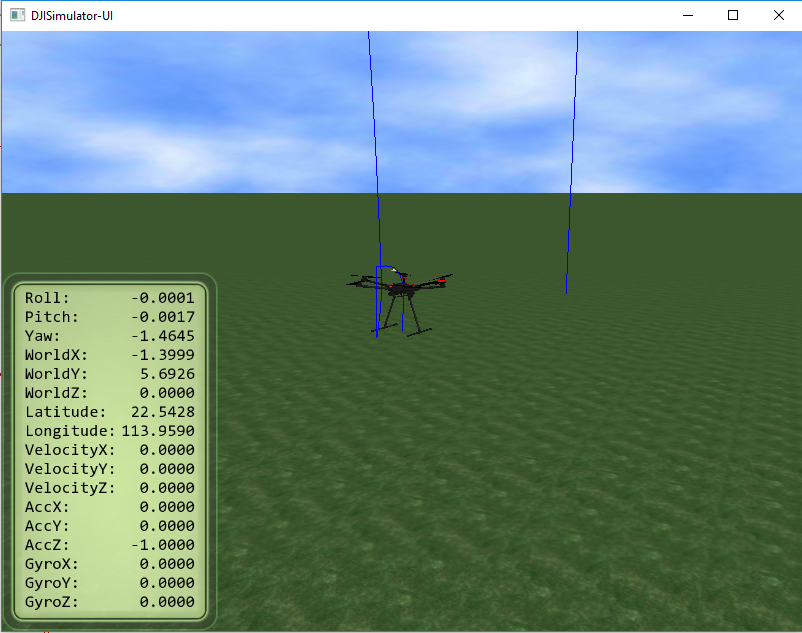

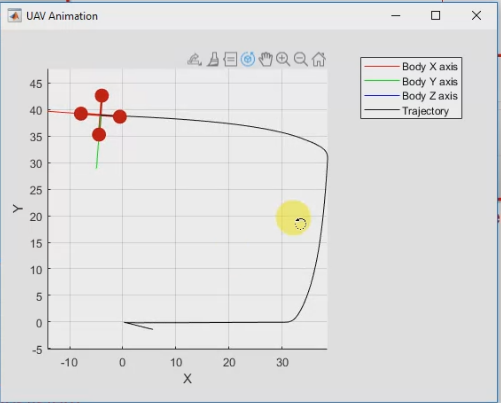

- You can try changing the waypoints in the *exampleHelperPublish_WayPoints.m* script during the simulation, to see the change in course.

## Task 4 - Deployment

The following figure shows the ROS Node block diagram during deployment.

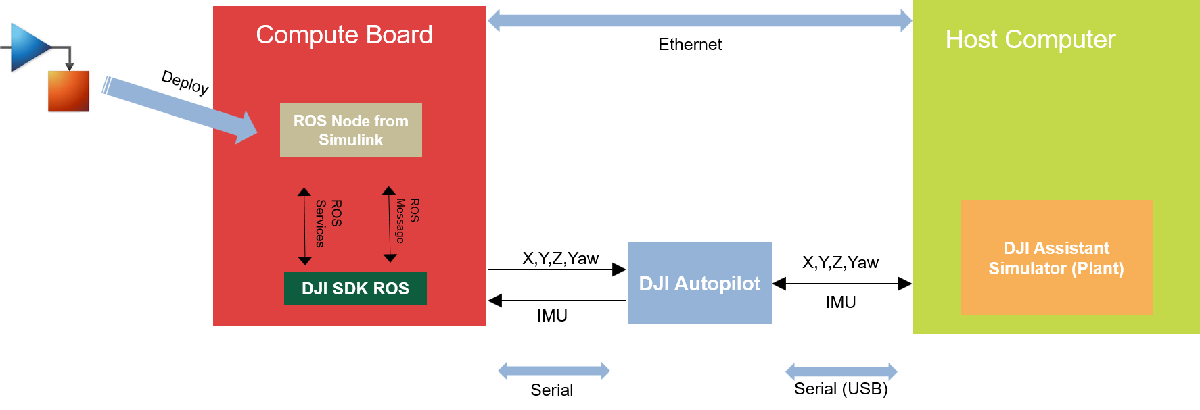

Once the Simulation is successfully performed (as explained in Task 3), you can build and deploy the Simulink model to the Compute board:

- Turn off the Slider switch because the UAV Animation block does not work in deployment. No other changes are required in the Simulink model.

- Click **Build and Run** on the Simulink Toolstrip.

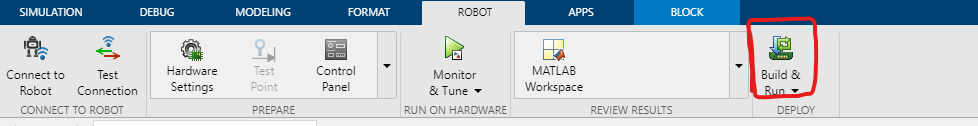 

Once the deployed model starts executing on the Compute board, the quadcopter following the waypoints can be visualized in the DJI Assistant Simulator.

## Other things to try

- Modify the Simulink model to include a controller in such a way to command the DJI N3 autopilot with roll angle, pitch angle and yaw rate by publishing to the topic ‘dji_sdk/ flight_control_setpoint_rollpitch_yawrate_zposition’

- Modify the Simulink model to develop a Orbit Follower application, instead of Waypoint Follower. Hint: Use the Orbit Follower block from UAV Toolbox.

## Troubleshooting 

Ensure that you follow these guidelines if you observe any issues while working with this example:

- Before starting the Simulation/Deployment of the demo model, ensure that the DJI Quadcopter is in the 'landed state'. You can see the DJI Assistant 2 simulator to know if the quadcopter is flying or it is landed. If it is flying, use the following helper function in the MATLAB command prompt to 'land' the quadcopter.

exampleHelperDJIDroneTaskControl('land')

- During Simulation/Deployment, if the quadcopter just takes off and does not follow the waypoints, this could be because the topic 'dji_sdk/local_position' is not returning the correct values. If this happens, stop the Simulation/execution of the deployed model. Ensure that the quadcopter is landed, as mentioned in the previous step. Then, execute the 'demo_flight_control' example shipped by the DJI Onboard ROS SDK by executing '*rosrun dji_sdk_demo demo_flight_control*' command in a terminal on the Compute board (you can refer to this [link](http://wiki.ros.org/dji_sdk/Tutorials/Running%20the%20flight%20control%20sample%20code) for details). Then, try simulating/deploying the Simulink model.

- After deploying the Simulink model onto the Compute board, to know if the Simulink model is running, execute the below commands:

d = rosdevice
d.AvailableNodes

- The above command should return all the available 'Simulink Nodes' on the Compute board. To find out if the Simulink model is running, execute the below command:

isNodeRunning(d, 'ros_dji_waypoint_follower')

- To stop the model, execute the below command

stopNode(d, 'ros_dji_waypoint_follower')

*Copyright 2020 The MathWorks, Inc.*